## 先進プラズマ理工学 report  2023/4/26

clear all;

%パラメータ設定
r = linspace(0,2,1000);
a = 0.25;
x = r./a;
R0 = 1;
n = 2;
m1 = -2;
m2 = -3;

(1)

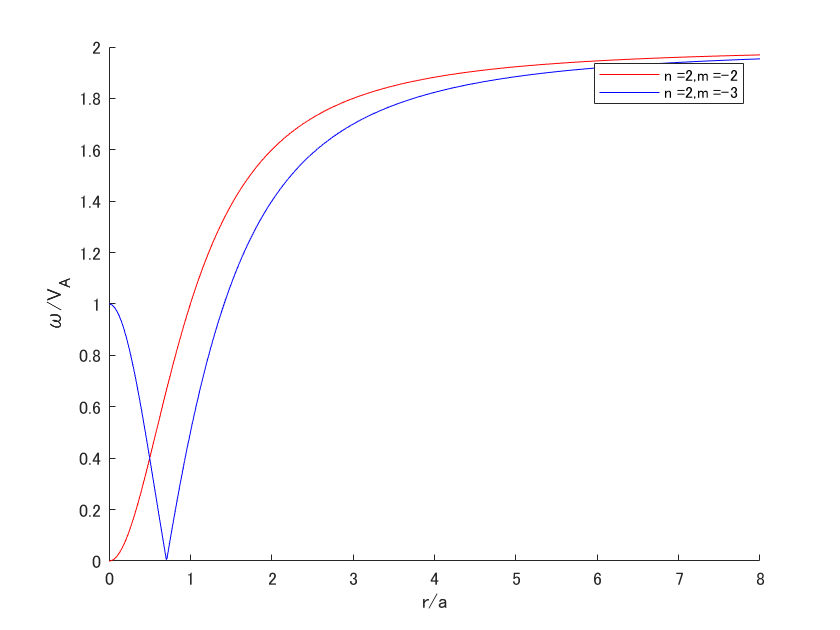

km1 = alfven_resonance_freq(n,m1,r,a,R0);
km2 = alfven_resonance_freq(n,m2,r,a,R0);

figure;
hold on
plot(x, km1,'r');
plot(x, km2,'b');
%xlim([0,1]);
xlabel('r/a');
ylabel('ω/V_A');
legend(strcat('n = ', num2str(n),',',' ','m = ',num2str(m1)), strcat('n = ', num2str(n),',',' ','m = ',num2str(m2)));
hold off

(2)

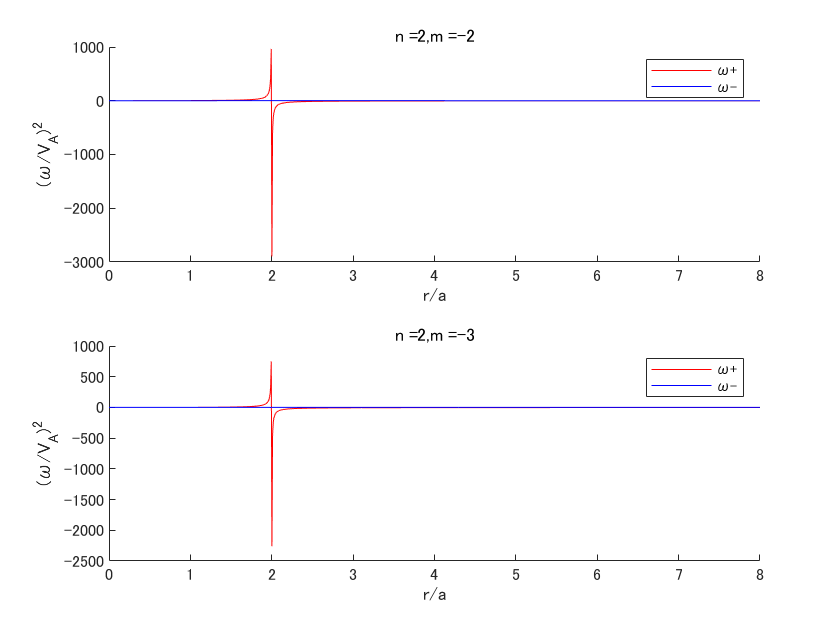

[p_y1,n_y1] = alfven_resonance_freq_toroidal(n,m1,r,a,R0);
[p_y2,n_y2] = alfven_resonance_freq_toroidal(n,m2,r,a,R0);


figure;
subplot(2,1,1);
hold on
plot(x, p_y1,'r');
plot(x, n_y1,'b');
%xlim([0,1]);
xlabel('r/a');
ylabel('(ω/V_A)^2');
legend('ω+','ω-');
title(strcat('n = ', num2str(n),',',' ','m = ',num2str(m1)));
hold off

subplot(2,1,2);
hold on
plot(x, p_y2,'r');
plot(x, n_y2,'b');
%xlim([0,1]);
xlabel('r/a');
ylabel('(ω/V_A)^2');
legend('ω+','ω-');
title(strcat('n = ', num2str(n),',',' ','m = ',num2str(m2)));
hold off

(3)

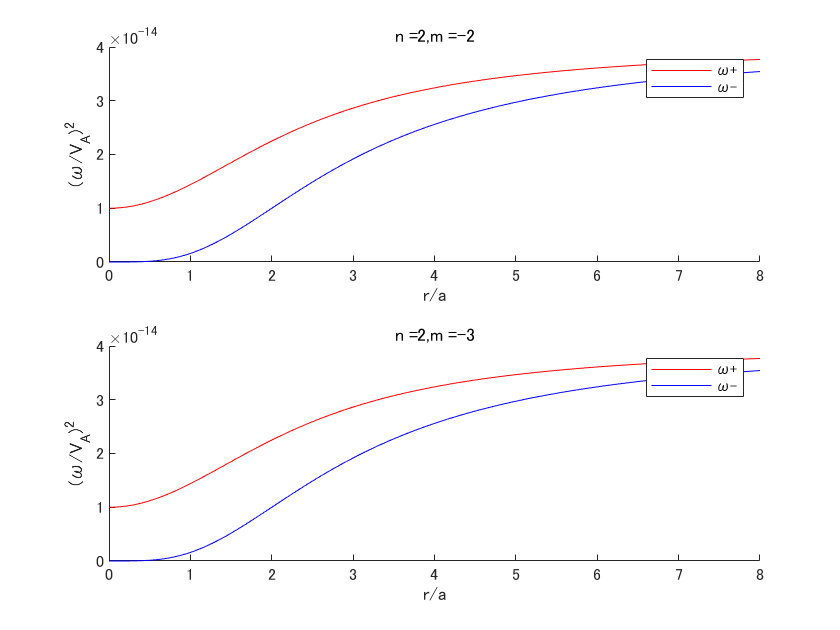

clearvars -except a x n m1 m2
r = linspace(0,1,1000);
R0 = 10000000;

[p_y1,n_y1] = alfven_resonance_freq_toroidal(n,m1,r,a,R0);
[p_y2,n_y2] = alfven_resonance_freq_toroidal(n,m1,r,a,R0);
figure;
subplot(2,1,1);
hold on
plot(x, p_y1,'r');
plot(x, n_y1,'b');
xlabel('r/a');
ylabel('(ω/V_A)^2');
legend('ω+','ω-');
title(strcat('n = ', num2str(n),',',' ','m = ',num2str(m1)));
hold off

subplot(2,1,2);
hold on
plot(x, p_y2,'r');
plot(x, n_y2,'b');
xlabel('r/a');
ylabel('(ω/V_A)^2');
legend('ω+','ω-');
title(strcat('n = ', num2str(n),',',' ','m = ',num2str(m2)));
hold off

function km = alfven_resonance_freq(n,m,r_array,a,R0)
% 定数
x_array = r_array./a;
q = 1+x_array.^2;
km = sqrt((R0.^-2)*(n + m./q).^2);

end

function [p_y, n_y] = alfven_resonance_freq_toroidal(n,m,r_array,a,R0)
% 定数
km = alfven_resonance_freq(n,m,r_array,a,R0);
km1 = alfven_resonance_freq(n,m+1,r_array,a,R0); 

sq_km = km.*km;
sq_km1 = km1.*km1;

sq_x = (2.*r_array./R0).^2;

p = sq_km+sq_km1 + sqrt((sq_km-sq_km1).^2 + 4.*sq_km.*sq_km1.*sq_x);
n = sq_km+sq_km1 - sqrt((sq_km-sq_km1).^2 + 4.*sq_km.*sq_km1.*sq_x);
under =  2.*(1-sq_x);

p_y = p./under;
n_y = n./under;
clearvars -except p_y n_y;
end